# Trajectory - TASK 2

### Robot characteristic

%Definizione delle caratteristiche del robot
clc 
clear all
close all
set(0, 'DefaultFigureRenderer', 'painters');
load_robot_specs


### 1) Trajectory Planning

R = 0.5; dH = 0.1;
P0 = [l0/2 1.1 h-0.1];
v_cost = 2;
[s, v, a, dt] = trajectory_planning(R,dH,50,P0,v_cost);


### 1) Kinematics - gripper coordinates 

#### 
$$\dot{Q} = J\dot{S}$$


Calculate the trajectory


$$\dot{J}_s \dot{S} + J_s \ddot{S} + \dot{J} _q \dot{Q}+J_q\ddot{Q}=0$$


for i = 1:1:length(s)

    if i==1
        guess = [130*pi/180 50*pi/180];
    else
        guess = q(i-1,:);
    end
    q(i,:) = inverse_kinematics(s(i,:),L,guess); 
    [J, J_s, J_q] = Jacobian(s(i,:),q(i,:),L);
    qp(i,:) = J*v(i,1:2)';
    qpp(i,:) = -inv(J_q)*((Jp_s(q(i,:),qp(i,:),v(i,1:2),L)*v(i,1:2)'+J_s*a(i,1:2)'+Jp_q(s(i,:),q(i,:),qp(i,:),v(i,1:2),L)*qp(i,:)'));
    
end

### 2D Plot

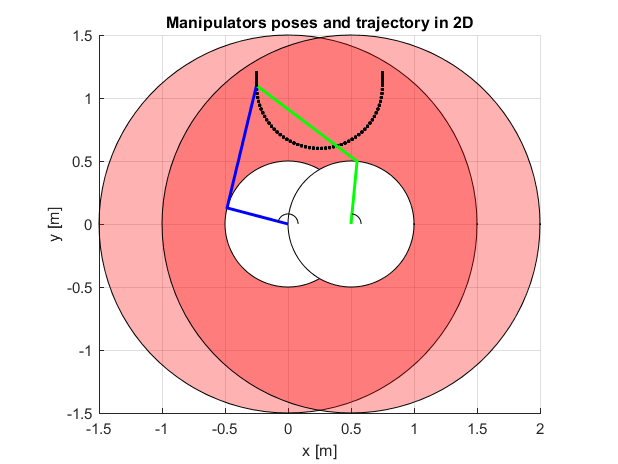

close all

figure(1)
% Plot workspace
center_x = 0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius*cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)
center_x = l0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)

center_x = 0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')

center_x = l0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')
axis equal
grid on

for i=1:length(s)
    % Print
    [config1, theta(i)] = plot2D_1st(q(i,:),L,1,s(i,1),s(i,2));
    [config2, gamma(i)] = plot2D_2nd(q(i,:),L,1,s(i,1),s(i,2));
    plot(s(i,1),s(i,2),'.-black')
    % Plot the angle arc
    h1 = plotAngleArc([0,0],0.08,[0,q(i,1)],'k-',1); %alfa
    h2 = plotAngleArc([l0,0],0.08,[0,q(i,2)],'k-',1); %beta
    
    pause(dt)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(h1); delete(h2);
    hold off
    title('Manipulators poses and trajectory in 2D');
    xlabel('x [m]')
    ylabel('y [m]')
end

### 3D Plot

close all
figure(2)
plot3(0,0,0,'LineWidth',4,'color','red') 
xlim([-l1-l2,l0+l1+l2]);
ylim([-l1-l2,l1+l2]);
zlim([0,h]);
xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
title('Manipulators poses and trajectory in 3D');
grid on
for i=1:length(s)
    % Print
    [config1, theta(i)] = Plot3D_1st(q(i,:),L,2,s(i,1),s(i,2));
    [config2, gamma(i)] = Plot3D_2nd(q(i,:),L,2,s(i,1),s(i,2));
    config3 = Plot3D_3rd(L,2,s(i,1),s(i,2),s(i,3));
    plot3(s(i,1),s(i,2),s(i,3),'.-black');
    
    pause(dt)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(config3)
end
hold off


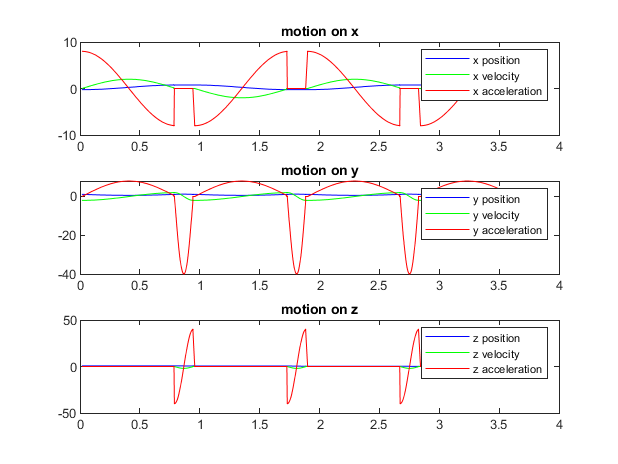

figure(3)

subplot(3,1,1)
tt=dt;
for i=2:length(dt)
    tt(i)=tt(i)+tt(i-1);
end

plot(tt,s(1:end-1,1),'blue',tt,v(1:end-1,1),'green',tt,a(1:end-1,1),'red')
title('motion on x')
legend('x position','x velocity','x acceleration')
subplot(3,1,2)
plot(tt,s(1:end-1,2),'blue',tt,v(1:end-1,2),'green',tt,a(1:end-1,2),'red')
title('motion on y')
legend('y position','y velocity','y acceleration')
subplot(3,1,3)
plot(tt,s(1:end-1,3),'blue',tt,v(1:end-1,3),'green',tt,a(1:end-1,3),'red')
title('motion on z')
legend('z position','z velocity','z acceleration')

### 1a) Print $\alpha ,\beta ,\gamma \;$and $\theta$

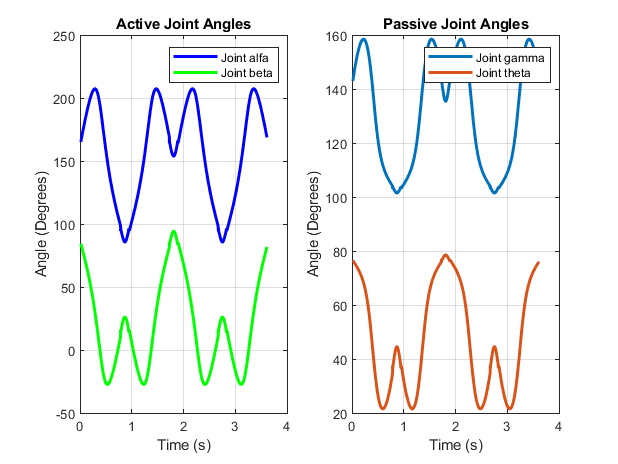

figure(4)
% alpha e beta
subplot(1,2,1)
plot(tt,q(1:end-1,1)*180/pi,'b','LineWidth',2);
hold on
plot(tt,q(1:end-1,2)*180/pi,'g','LineWidth',2);
hold off
title('Active Joint Angles')
xlabel('Time (s)')
ylabel('Angle (Degrees)')
grid on
legend('Joint alfa','Joint beta')

% gamma e theta
subplot(1,2,2)
plot(tt,gamma(1:end-1)*180/pi,'LineWidth',2);
hold on
plot(tt,theta(1:end-1)*180/pi,'LineWidth',2);
hold off
title('Passive Joint Angles')
xlabel('Time (s)')
ylabel('Angle (Degrees)')
grid on
legend('Joint gamma','Joint theta')

### 1b) Debug

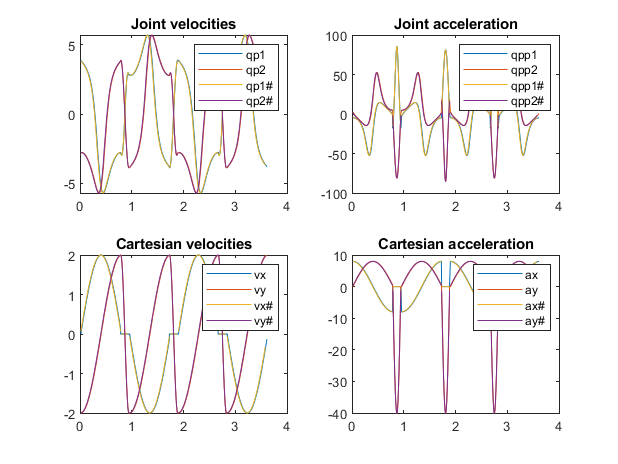

figure(5)
% Joint
for i=2:1:(length(dt)-1)
    qp_alfa_debug(i-1) = (q(i,1)-q(i-1,1))/dt(i-1);
    qp_beta_debug(i-1) = (q(i,2)-q(i-1,2))/dt(i-1);

    qpp_alfa_debug(i-1) = (qp(i,1)-qp(i-1,1))/dt(i-1);
    qpp_beta_debug(i-1) = (qp(i,2)-qp(i-1,2))/dt(i-1);
end

subplot(2,2,1)
plot(tt,qp(1:end-1,1),tt,qp(1:end-1,2),tt(1:end-2),qp_alfa_debug,tt(1:end-2),qp_beta_debug);
legend('qp1','qp2','qp1#','qp2#');
title('Joint velocities')
subplot(2,2,2)
plot(tt,qpp(1:end-1,1),tt,qpp(1:end-1,2),tt(1:end-2),qpp_alfa_debug,tt(1:end-2),qpp_beta_debug);
legend('qpp1','qpp2','qpp1#','qpp2#')
title('Joint acceleration')

% Cartesian
for i=2:1:(length(dt)-1)
    vx_debug(i-1) = (s(i,1)-s(i-1,1))/dt(i-1);
    vy_debug(i-1) = (s(i,2)-s(i-1,2))/dt(i-1);

    ax_debug(i-1) = (v(i,1)-v(i-1,1))/dt(i-1);
    ay_debug(i-1) = (v(i,2)-v(i-1,2))/dt(i-1);
end

subplot(2,2,3)
plot(tt,v(1:end-1,1),tt,v(1:end-1,2),tt(1:end-2),vx_debug,tt(1:end-2),vy_debug);
legend('vx','vy','vx#','vy#');
title('Cartesian velocities')
subplot(2,2,4)
plot(tt,a(1:end-1,1),tt,a(1:end-1,2),tt(1:end-2),ax_debug,tt(1:end-2),ay_debug);
legend('ax','ay','ax#','ay#')
title('Cartesian acceleration')

### 2) Dynamics


$$F_q = ({J_e}^t M J_e)\ddot{Q}+{J_e}^tM\dot{J_e}\dot{Q}-{J_e}^tF_{se}$$


% Je_0 = Jacobian_Ext(q(1,:),L,G,J);
% 
% for i = 1:length(s)
%     Je = Jacobian_Ext(q(i,:),L,G,J);
%     if i==1 
%         Jep=Je./dt(1);
%     else
%         Jep=(Je-Je_0)/dt(i);
%     end
%     Fq(i,:) = (Je'*M*Je)*qpp(i,:)' + (Je'*M*Jep)*qp(i,:)'-transpose(Je)*Fse;
%     
%     Se=direct_dynamics(q(i,:),s(i,:),L,G);
%     Sep = Je*qp(i,:)';
%     Ek(i,:) = (1/2)*Sep'*M*Sep;
%     Ep(i,:) = transpose(Ag)*M*Se;
%     E_tot(i,:) = Ep(i,:) + Ek(i,:);
%     W(i,:)=qp(i,:)*Fq(i,:)'+Sep'*Fse;
% 
% end
% 

### 2a) Actuator torques

% figure(6)
% subplot(1,2,1)
% plot(tt,Fq(:,1),tt,Fq(:,2),'LineWidth',2)
% title("Actuator torques")
% legend('c1','c2')
% grid on
% 
% subplot(1,2,2)
% W_debug = diff(E_tot)/dT;
% plot(tt(1:end-1),W_debug);
% hold on
% plot(tt,W);
% hold off
% title("Force Power")
% legend('Motor + ext. force power', 'Deriv. tot Energia')
% grid on